# Descriptors per cada senyal

llindar = 20;
dibuixar = false;
for senyal=0:42
    iActual = imread(strcat("Models\Meta\", int2str(senyal),'.png'));   
    iBW = imbinarize(iActual);
    iRectas = buscarRectas(iActual, false,5);
    pendents(senyal+1).pendientes = range([iRectas.theta]);
    pendents(senyal+1).nombre = numberToName(senyal+1);
    pendents(senyal+1).liniesParaleles = range([iRectas.theta])<= llindar;
        
    if dibuixar        
        figure 
        subplot(1,4,1)
        imshow(iActual);
        subplot(1,4,2)
        imshow(iBW(:,:,1));
        subplot(1,4,3)
        imshow(iBW(:,:,2));
        subplot(1,4,4)
        imshow(iBW(:,:,3));
    end
end

## Hough

Podem aplicar Hough per reconeixer les rectes, pero compararem el rang de les pendents de les rectes Ens permet discriminar les senyals amb linies rectes com la senyal 9 o 32.

Podem considerar aquest valor amb un llindar, 1 per valors de rang < 8 i 0 per valors superiors.

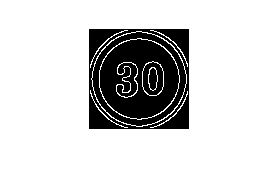

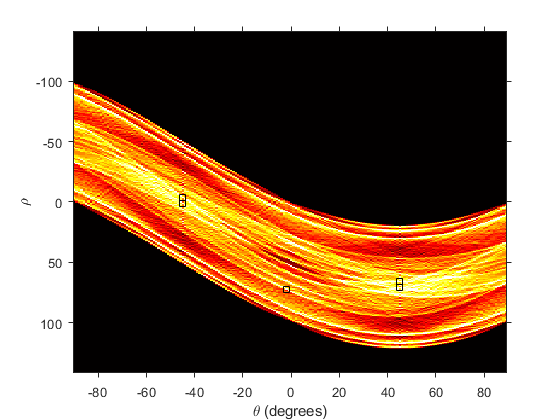

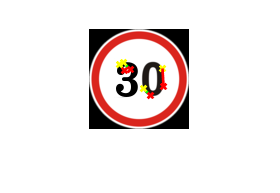

i6lines = buscarRectas(imread("Models\Meta\6.png"), false,5);
i2lines = buscarRectas(imread("Models\Meta\1.png"), true,5); %valor alto

i32lines = buscarRectas(imread("Models\Meta\32.png"), false,5);
i41lines = buscarRectas(imread("Models\Meta\41.png"), false,5);
i42lines = buscarRectas(imread("Models\Meta\42.png"), false,5);
%podem calcular el pendent de cada recta per veure quin tipus de rectes
%s'han trobat

range([i6lines.theta])

ans = 2

range([i2lines.theta])

ans = 43

range([i32lines.theta])

ans = 13

range([i41lines.theta])

ans = 3

range([i42lines.theta])

ans = 15